# 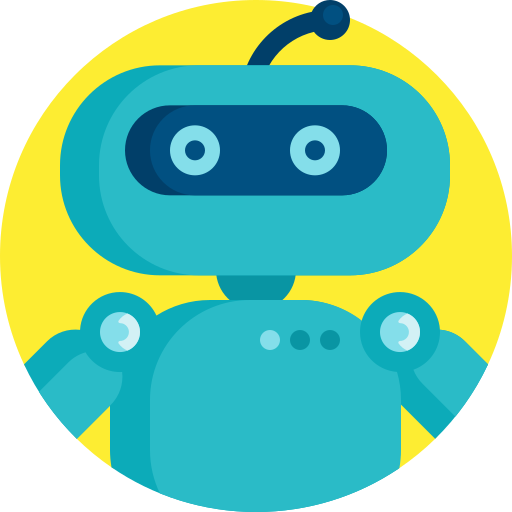

# **MEC4127F: Introduction to Robotics**

# Chapter 6: Wheeled robot kinematics

## 6.1 Introduction

This Chapter extends our understanding of forward and inverse kinematics to wheeled robots. Unlike open-chain robotic arms, conventional wheeled robots have kinematic constraints that make the forward kinematic formulation incomplete. By extension, the inverse kinematic solution can only be partially solved. That being said, the concept of forward and inverse kinematics can still be used to effectively model the wheeled robot and incorporate the knowledge into a feedforward control scheme.

### 6.1.1 Wheeled mobile robots

There are a range of different types of wheeled robots contained within modern robotics. We will primarily consider convention wheeled robots that have non-holonomic constraints (more on this later). Two common types of wheeled robots are:

- Car-like robots

- Differentially-steered robots

#### 6.1.1.2 Car-like robots

Analogous to commercial automotive vehicles, car-like robots have two controllable actuators that relate to the steering angle and forward velocity of the robot. Car-like robots are a very effective class of vehicle — hence their ubiquity on modern transportation. That being said, there is added mechanical complexity in accounting for the steering mechanism of the front wheels, as well as their requirement to have a differential gearbox. Car-like robots are also not able to turn on the spot, which increasing the complexity in performing trajectory following. Car-like robots can be generalised using the bicycle model.

#### 6.1.1.1 Differentially-steered robot

We will consider a particular type of wheeled robot in this course, known as a differentially-steered robot. The differentially-steered robot makes use of two active wheels that are controlled independently, and a passive wheel that is required for stability. A good example of this type of wheeled robot is an automated vacuum cleaner. The benefits of these types of wheeled robots is that translational and rotational velocity is decoupled, which allows for useful motion, such as turning on the spot. Differentially-steered robots can be generalised using a unicycle model. An example of a differentially-steered robot is shown in Figure 6.1

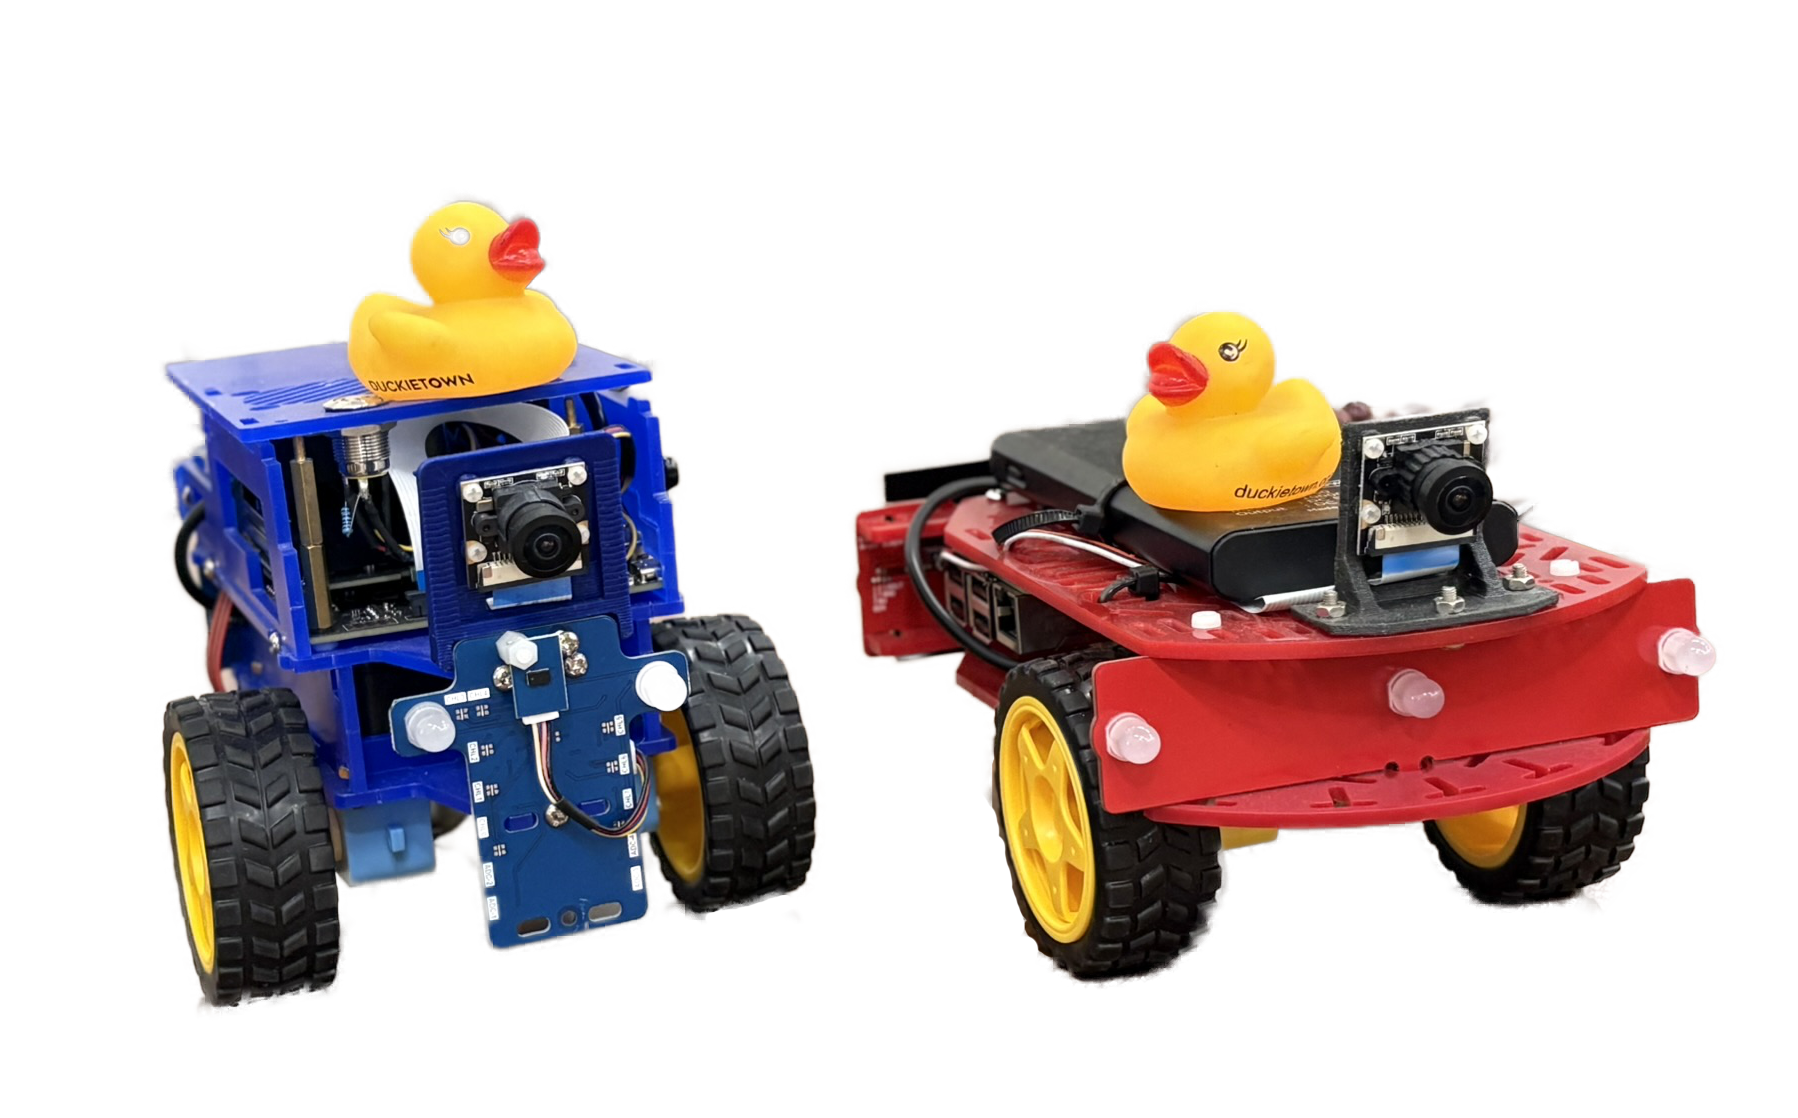

**Figure 6.1:** The DuckieBot, a differentially-steered robot that is used in the MechatronicSystems.Group for research

### 6.1.3 Robotics toolbox

This Chapter will make use of `MATLAB`'s [Robotics System Toolbox](https://in.mathworks.com/help/robotics/index.html) to generate various visualisations of wheeled robots. The toolbox can be used to visualise pose and also model the kinematics of a wheeled robot with high-level commands.

An example is given below, which will be explored in detail later on in the Chapter, as well in the relevant Virtual Lab. For now, feel free to play with the sliders!

clear
kinematicModel = differentialDriveKinematics(WheelRadius=0.05,TrackWidth=0.1,VehicleInputs="VehicleSpeedHeadingRate");
dT = 0.1;
timer = rateControl(1/dT);

v = 10; %m/s
psi_dot = 3; %rad/s

figure(1)
robotPose = [0 0 0]';
for i=1:(5/dT)  %run the simulation for a time equivalent to 5 seconds
    clf
    u = [v psi_dot]';
    robotVelocity = derivative(kinematicModel,robotPose,u);
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
    
    axis([-20 20 -20 20]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", 20*kinematicModel.TrackWidth);

    drawnow
    waitfor(timer);
end

## 6.2 Holonomic and non-holonomic robots

Using our results from **Chapter 5**, we were able to determine that our 2R robot pose is uniquely defined by the two joint angles $\{\alpha,\beta\}$. These joint angles can be measured using encoders or potentiometers, and assuming the sensors possess sufficient resolution (and the links remain rigid with no out of plane motion), we will have an accurate description of our end-effector pose. 

As we will see in this Chapter, the forward kinematic problem for a wheeled robot is a bit more involved. We can still use encoders to measure our robot wheel velocity and/or orientation, but the displacement of the robot in the  $\hat{\mathbf x}_W$ - $\hat{\mathbf y}_W$ plane will be the accumulation (or integration) of said wheel orientations. An important note is that for so-called **non-holonomic** systems, it is not sufficient to simply measure the distance that each wheel has travelled, but also *when* each movement was executed. 

The 2R robotic arm that we considered in **Chapter 5** is **holonomic**, as each joint position combination in the actuator space uniquely describes the end-effector pose in $\{W\}$. In other words, there is an algebraic relationship that maps $\mathcal{A}\rightarrow \mathcal{T}$. For example, for  $\alpha=\beta=0$ , the position of the end-effector always equals  $(l_1+l_2,0)$ , regardless of the trajectory that the end-effector followed prior to this point. 

Another way to think of holonomic systems is that they are able to instantaneously move in any direction of their configuration space. The robot arm can at any time increase or decrease either of its joint angles, so there is no limitation on its directional movement in C-space. The only exception is when the robot is in a singularity (for example when the robot arm is straight ($\beta=0$), thereby preventing motion in that direction).

A conventional wheeled robot is an example of a non-holonomic vehicle. The configuration space is made up of the position and orientation — $(x,y,\psi)$, but wheeled robots cannot traverse in the direction of the wheel axis, only perpendicular to it. As a result, one cannot instantaneously move in any direction in the C-space of a conventional wheeled robot. When there are limitations on how a robot can move in its C-space, this is referred to as a (*non-holonomic) kinematic constraint*. 

#### **Definition:** Non-holonomic kinematic constraint

A *non-holonomic kinematic constraint* is a kinematic constraint that is a function of "derivatives of positional variables" and cannot be integrated to provide a constraint in terms of positional variables. 

A non-holonomic constraint does not limit the accessible configurations, but limits the paths that can be followed to reach them. A non-holonomic kinematic constraint relies on a differential relationship, such as requiring the derivative of a position, which means that the constraint cannot be represented at the position level (preventing a direct mapping to the task space). For this reason, non-holonomic systems are often referred to as *non-integrable* systems. As we will see for conventional wheeled robots, while we cannot map from the actuator space to the task space (where pose is described), we can still map to a description of pose rate. Once we have done this, we can then use integration to move from pose rate to pose.

## 6.3 Forward kinematics of wheeled robots

This Section will detail the forward kinematics of a differentially-steered robot. The derivation for other wheeled robots, such as car-like robots follows a similar procedure.

### 6.3.1 Determining the pose rate

The non-holonomic nature of the wheeled robot can be further understood by examining the underlying kinematics of the system in question. With reference to Figure 6.2, the differentially-steered robot comprises: 

- two independently controlled wheels that are equidistant from the robot centre of mass; 

- a passive caster wheel that is required for stability and will orient itself appropriately, based on the robot motion. The rest of the robot is static. 

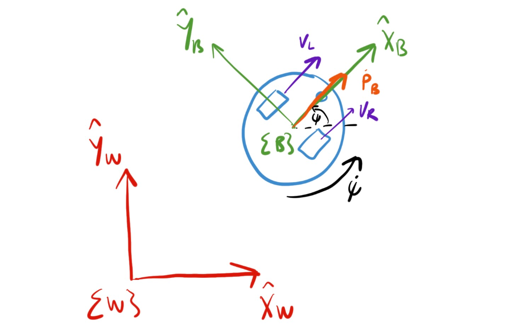

**Figure 6.2:** Overview of differentially-steered robot.
 

We can attach frame $\{W\}$ to our static room, and attach $\{B\}$ to our robot. In particular, we will attach $\{B\}$ to the robot such that $\hat{\bf y}_B$ is parallel to the wheel axes. We will assume that our wheeled robot only operates on the  $\hat{\mathbf x}_W$-$\hat{\mathbf y}_W$ plane, which implies that the robot pose can be described in SE(2) using the pose vector


$${^W\mathbf\xi}_B =
\left[\begin{array}{cc}    {^W{\bf t}_B} \\ \psi     \\ \end{array}\right]
=
\left[\begin{array}{cc}    {{t}_x} \\ {{ t}_y} \\ \psi \end{array}\right]
\in \mathbb{R}^3.$$


It is common practice for the forward direction of the wheeled robot to correspond with the $\hat{\mathbf x}_B$-axis, with the direction of the $\hat{\mathbf y}_B$-axis varying depending on whether  $\hat{\mathbf z}_B$ points up or down. In this course we will assume that $\hat{\mathbf z}_B$ points "upwards", which makes the the $\hat{\mathbf y}_B$-axis point "leftwards" of the robot. 

With reference to the equation above, we can describe our robot's pose rate in $\{W\}$ using  


$${^W\dot\mathbf\xi}_B =
\left[\begin{array}{cc}    {^W\dot{\bf t}_B} \\ \dot\psi     \\ \end{array}\right]
=
\left[\begin{array}{cc}    {\dot{t}_x} \\ {\dot{ t}_y} \\ \dot\psi \end{array}\right]
\in \mathbb{R}^3.$$


As previously stated, the kinematic constraint on the wheeled robot implies that translational velocity can only occur parallel or anti-parallel to the $\hat{\mathbf x}_B$-axis, as shown in Figure 6.2. As such, the translational velocity in $\{B\}$ is described by 


$${^B{\bf v}}=[v~~0]^T.$$
 

Given that $\hat{\bf z}_W=\hat{\bf z}_B$, the rotational velocity in $\{W\}$ will be equivalent to that of $\{B\}$, namely


$${^W\dot{\psi}}={^B\dot{\psi}}={\dot{\psi}}.$$


The first step in defining the forward kinematic mapping is to determine the relationship between velocity behaviour in $\{B\}$ and pose rate behaviour in $\{W\}$. We begin by mapping the body-frame velocities to the world frame using our understanding of rotation matrices. Consulting Figure 6.2, the robot's translational velocity in $\{W\}$ is given by


$${^W\dot{\bf t}_B} = {^W{\bf R}_B} {^B{\bf v}},$$


where the rotation matrix in SO(2) is given by


$$\begin{array}{cc}{^W{\mathbf R}_B} = \left[\begin{array}{cccccccc}    \cos{\psi} & -\sin{\psi} \\    \sin{\psi} & \cos{\psi} \\ \end{array}\right]. \end{array}$$


The mapping can be written explicitly as


$$\left[\begin{array}{cc}    {\dot{t}_x} \\ {\dot{ t}_y}  \end{array}\right]=v\left[\begin{array}{cc}    \cos\psi \\ \sin\psi  \end{array}\right].$$


We have already established that ${^W\dot{\psi}}={^B\dot{\psi}}={\dot{\psi}}$, which can be added to the equation above to describe the full mapping between velocities in $\{B\}$ and $\{W\}$:


$$\left[\begin{array}{cc}    {\dot{t}_x} \\ {\dot{ t}_y}  \\ \dot\psi \end{array}\right]=\left[\begin{array}{cc}    v\cos\psi \\ v\sin\psi\\ \dot\psi  \end{array}\right].$$


The equation above is often referred to as the unicycle model.

The only question we need to answer now is how to calculate the body-frame velocities. We do this by incorporating a kinematic constraint related to the robot wheels. For a conventional, idealised wheel, the kinematic constraints are that every rotation of the wheel leads to *strictly* forward or backward motion and does not allow for sideslip motion, sliding, or periods of non-contact with the surface. With reference to Figure 6.3, this enables us to calculate the translational velocity of left wheel, $v_L$ , and right wheel, $v_R$ , using the respective rotational speeds, $\dot{\phi}_L$ and $\dot{\phi}_R$, and fixed wheel radius, $r_W$, namely


$$\begin{array}{cc}    v_L= \dot{\phi}_Lr_W,\\ \end{array}$$



$$\begin{array}{cc}v_R= \dot{\phi}_Rr_W.\end{array}$$


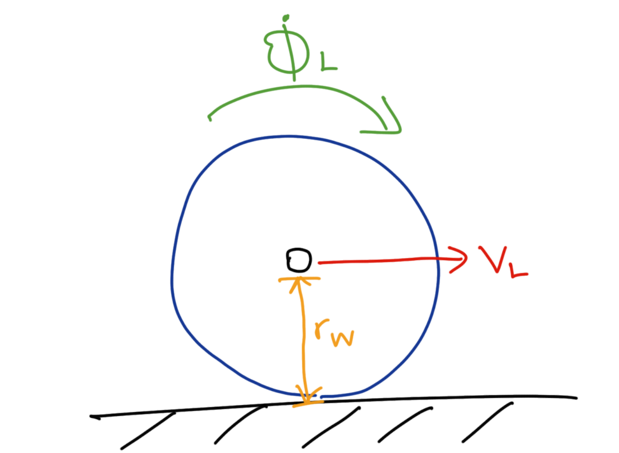

**Figure 6.3: **Relationship between translational and angular velocity of wheel.

### 6.3.2 Instantaneous centre of rotation

Referring to Figure 6.4, the vehicle follows a curved path centered on the *Instantaneous Centre of Rotation* (ICR). 

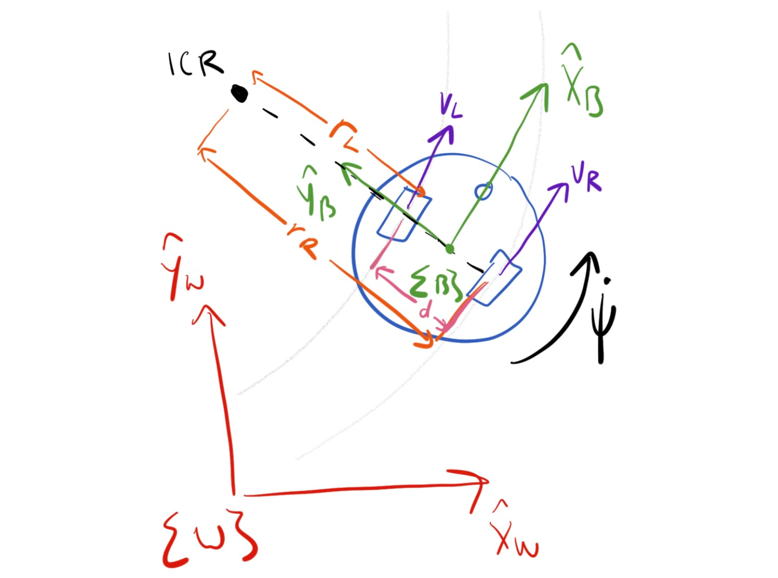

**Figure 6.4:** Differentially-steered robot following a path around the Instantaneous Centre of Rotations (ICR).
 

#### **Definition:** Instantaneous centre of rotation

The **instantaneous centre of rotation** (ICR) is the point fixed to a body undergoing planar movement that has zero velocity at a particular instant of time. 

As the linear motion along the circumference of a circle is tangent to the circle, there is no motion pointing towards this instantaneous centre. This allows us to draw radial lines (lines of no motion) that emerge from the instantaneous centre and intersect our wheel plane centres. The instantaneous angular velocity our platform follows as 


$$\begin{array}{cc}\dot{\psi} = \frac{v_L}{r_L} = \frac{v_R}{r_R},\end{array}$$


where $v_L$ and $v_R$ are the linear velocities experienced by the wheel centres, and $r_L$ and ${r_R}$ are the respective radii from the ICR to the two wheel centres. The concept of the ICR can be extended to other types of wheeled robots and is essential in deriving the robot forward kinematics. The distance from the wheel-to-wheel centre and ICR is given by 

$r=\frac{r_L+r_R}{2}=\left|\frac{v}{\dot\psi}\right|$.

By extension, the position of the ICR in $\{B\}$ is given by

${^B{\bf p}_{icr}=[0~~\frac{v}{\dot\psi}]^T$,

where $\text{sgn}(\frac{v}{\dot\psi})$ determines whether the ICR is located on the positive or negative $\hat{\bf y}_B$ axis — Figure 6.4 assumes that $\text{sgn}(\frac{v}{\dot\psi})>0$ based on the assumption that $v$ and $\dot\psi$ are both positive. Based on the equation above, we can easily deduce the following:

- $v\rightarrow 0$ implies that the ICR will approach the frame $\{B\}$ origin;

- $\dot\psi\rightarrow 0$ implies that the ICR will tend to infinity, with the polarity dependent on $\text{sgn}(\frac{v}{\dot\psi})$.

If we know the pose of our robot in $\{W\}$ we can determine the location of the ICR in the world frame. Making use of our generalised vector mapping, this is given by


$${^W{\bf p}_{icr}={^W{\bf R}_B}{^B{\bf p}_{icr}+{^W{\bf t}_B}.$$


#### Example: Instantaneous centre of rotation

The simulation resulting from the code block below shows how the ICR moves around as a a function of the body velocities and current robot pose. We should notice that:

- the ICR always lies on the $\hat{\bf y}_B$ axis.

- as $\dot\psi\rightarrow 0$, the ICR moves further away from the robot, as a large circular arc is being followed;

- as $v\rightarrow0$, the ICR approaches the wheel-to-wheel midpoint, which is also equivalent to the origin of $\{B\}$;

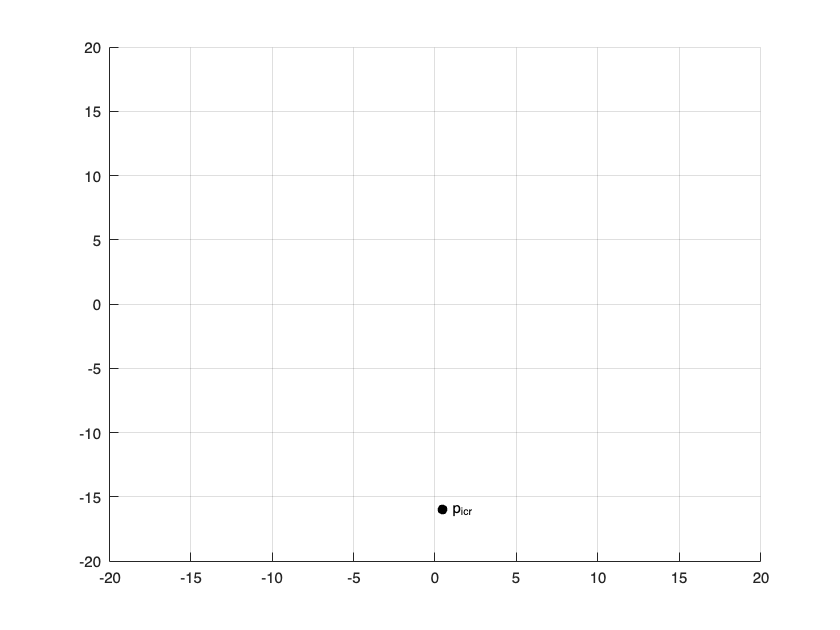

clear
kinematicModel = differentialDriveKinematics(WheelRadius=0.5,TrackWidth=0.2,VehicleInputs="VehicleSpeedHeadingRate");
dT = 0.1;
timer = rateControl(1/dT);

v = 6.5; %m/s
psi_dot = -0.4; %rad/s

r = v/psi_dot;
pb_ICR = [0 r]';

figure(1)
robotPose = [0 0 0]';
for i=1:(5/dT)  %run the simulation for a time equivalent to 5 seconds
    clf,hold on
    u = [v psi_dot];
    robotVelocity = derivative(kinematicModel,robotPose,u);
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
    
    axis([-20 20 -20 20]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", 10*kinematicModel.TrackWidth);
    
    psi = robotPose(3);
    t = robotPose(1:2);
    pw_icr = t+[cos(psi) -sin(psi); sin(psi) cos(psi)]*pb_ICR;
    plot(pw_icr(1),pw_icr(2),'ko',MarkerFaceColor='k')
    text(pw_icr(1)+0.5,pw_icr(2),'p_{icr}')
    drawnow
    waitfor(timer);
end

### 6.3.3 Relating wheel speeds to pose rate

We can relate our virtual unicycle model to the differentially-steered robot by using the concept of the ICR and its inherent relationship between wheel speeds and generalised motion.

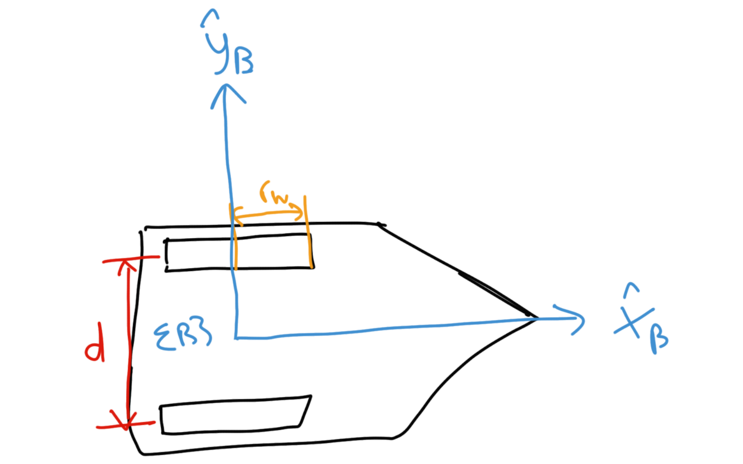

**Figure 6.5:** Top-down view of wheeled robot, showing physical parameters and location of $\{B\}$.

With reference to Figure 6.4 and Figure 6.5, the linear velocity in the direction of $\hat{\bf x}_B$ is aptly described as


$$\begin{array}{cc}v = \dot{\psi}\frac{r_L+r_R}{2}=\frac{v_L+v_R}{2}=\frac{r_W}{2}(\dot\phi_L+\dot\phi_R).\end{array}$$


This gives us a direct relationship between the wheel speeds and resulting translational velocity in $\{B\}$, owing to the fact that ${^B{\bf v}}=[v~~0]^T$. This can then be extended to $\{W\}$ using


$$\begin{array}{ll}\left[\begin{array}{cc}    ^W\dot{t}_x\\^W \dot{t}_y    \\ \end{array}\right]
&=&v \left[\begin{array}{cc}    \cos\psi\\\sin\psi \end{array}\right],\\
&=&  \frac{v_L+v_R}{2} \left[\begin{array}{cc}    \cos\psi\\\sin\psi \end{array}\right],\\
&=&  \frac{r_W}{2}(\dot\phi_L+\dot\phi_R)\left[\begin{array}{cc}    \cos\psi\\\sin\psi \end{array}\right].
\end{array}$$


Next, we need to relate the angular velocity of the wheels with the angular velocity of the robot body. Recalling that $\begin{array}{cc}\dot{\psi} = \frac{v_L}{r_L} = \frac{v_R}{r_R}\end{array}$, and noting that $r_R=r_L+d$, where $d$ is the distance between the wheel centres, the angular velocity can be expressed as


$$\begin{array}{cc}\dot{\psi} = \frac{v_L}{r_L} = \frac{v_R}{r_L+d}.\end{array}$$


After some rearranging, we obtain


$$\begin{array}{cc}
({r_L+d)\dot{\psi}  = v_R,\end{array}$$


which implies that 


$$\begin{array}{cc}\dot{\psi} = \frac{v_R-v_L}{d} ,\end{array}$$


based on $v_L=r_L\dot\psi$. Incorporating the above relationship into our wheel model, our explicit description of the robot angular velocity follows as


$$\begin{array}{cc}\dot{\psi}= \frac{r_W}{d}\left( \dot{\phi}_R-\dot{\phi}_L \right). \end{array}$$


 The coupled relationship between the wheel velocities and world-frame velocities can then be described explicitly as


$$\begin{array}{ll}\left[\begin{array}{cc}    ^W\dot{t}_x \\    ^W\dot{t}_y \\    \dot{\psi}    \\ \end{array}\right] &=&     \left[\begin{array}{cccccccc}    \cos{\psi} & -\sin{\psi} & 0\\    \sin{\psi} & \cos{\psi} & 0\\    0 & 0 & 1    \\ \end{array}\right]    \left[\begin{array}{cc}    \frac{r_W}{2}\left(\dot{\phi}_L+\dot{\phi}_R\right)\\    0 \\    \frac{r_W}{d}\left( \dot{\phi}_R-\dot{\phi}_L \right)    \end{array}\right],\\
&=& \left[\begin{array}{cc}    \frac{r_W}{2}\left(\dot{\phi}_L+\dot{\phi}_R\right)\cos\psi\\    \frac{r_W}{2}\left(\dot{\phi}_L+\dot{\phi}_R\right)\sin\psi \\    \frac{r_W}{d}\left( \dot{\phi}_R-\dot{\phi}_L \right)    \end{array}\right],\\
&=&  \left[\begin{array}{cc}    \frac{r_W}{2}\cos\psi & \frac{r_W}{2}\cos\psi\\    \frac{r_W}{2}\sin\psi & \frac{r_W}{2}\sin\psi \\  -\frac{r_W}{d} & \frac{r_W}{d}    \end{array}\right]
\left[\begin{array}{cc}    \dot\phi_L \\ \dot\phi_R   \end{array}\right].
\end{array}$$


syms psi r_W d phiL_dot phiR_dot real

A = [cos(psi) -sin(psi) 0;
     sin(psi)  cos(psi) 0;
     0         0        1];
dxi = A*[r_W/2*(phiL_dot+phiR_dot) 0 r_W/d*(phiR_dot-phiL_dot)]'

$$dxi = \left(\begin{array}{c} \frac{r_{W}\,\cos\left(\psi \right)\,\left(\dot{\mathrm{phiL}}+\dot{\mathrm{phiR}}\right)}{2}\\ \frac{r_{W}\,\sin\left(\psi \right)\,\left(\dot{\mathrm{phiL}}+\dot{\mathrm{phiR}}\right)}{2}\\ -\frac{r_{W}\,\left(\dot{\mathrm{phiL}}-\dot{\mathrm{phiR}}\right)}{d} \end{array}\right)$$

The equation above describes the direct mapping from our actuator parameters (the wheel angular velocities) to the task space velocities — the rate of change of our world-frame pose, ${^W\dot{\mathbf\xi}}_B$ . Note that our mapping does not inherently describe our robot's pose. This is because an integrator is required to relate velocities to positions. This will be discussed in the following section.

### 6.3.3 Mapping body velocities to wheel speeds

As previously shown, the velocities in $\{B\}$ are related to the wheel speeds based on


$$\begin{array}{cc}v = \dot{\psi}\frac{r_L+r_R}{2}=\frac{v_L+v_R}{2}=\frac{r_W}{2}(\dot\phi_L+\dot\phi_R).\end{array}$$



$$\begin{array}{cc}\dot{\psi} = \frac{v_R-v_L}{d}=\frac{r_W}{d}\left( \dot{\phi}_R-\dot{\phi}_L \right).\end{array}$$


This can be represented in matrix form as


$$\begin{array}{ll}\left[\begin{array}{cc}    v \\    \dot\psi \end{array}\right] &=&     \left[\begin{array}{cccccccc}    \frac{1}{2} & \frac{1}{2}\\    -\frac{1}{d} & \frac{1}{d} \end{array}\right]    \left[\begin{array}{cc}    v_L \\ v_R    \end{array}\right],\\
&=& r_W\left[\begin{array}{cc}    \frac{1}{2} & \frac{1}{2}\\    -\frac{1}{d} & \frac{1}{d}\end{array}\right]
\left[\begin{array}{cc}    \dot\phi_L \\ \dot\phi_R    \end{array}\right],\\
\end{array}$$


and the inverse relationships are easily obtained as


$$\begin{array}{ll}\left[\begin{array}{cc}    v_L \\   v_R \end{array}\right] &=&     \left[\begin{array}{cccccccc}    1 & -\frac{d}{2}\\    1 & \frac{d}{2} \end{array}\right]    \left[\begin{array}{cc}    v \\ \dot\psi    \end{array}\right],\\

\end{array}$$



$$\begin{array}{ll}\left[\begin{array}{cc}    \dot\phi_L \\   \dot\phi_R \end{array}\right] &=&     \frac{1}{r_W}\left[\begin{array}{cccccccc}    1 & -\frac{d}{2}\\    1 & \frac{d}{2} \end{array}\right]    \left[\begin{array}{cc}    v \\ \dot\psi    \end{array}\right].\\

\end{array}$$


syms d r_W v psi_dot real

A1 = [ 1/2 1/2;
     -1/d 1/d];
v_LR = A1\[v psi_dot]'

$$v\_LR = \left(\begin{array}{c} v-\frac{d\,\dot{\psi }}{2}\\ v+\frac{d\,\dot{\psi }}{2} \end{array}\right)$$


A2 = r_W*A1;
phi_dot_LR = A2\[v psi_dot]'

$$phi\_dot\_LR = \left(\begin{array}{c} \frac{2\,v-d\,\dot{\psi }}{2\,r_{W}}\\ \frac{2\,v+d\,\dot{\psi }}{2\,r_{W}} \end{array}\right)$$

The result above is useful if we know the body velocities that are required for a particular motion and want to determine the corresponding wheel speeds.

#### Example: Relationship between wheel speeds and body velocity

The code block provides a visualisation of the mapping between velocities in $\{B\}$ and wheel speeds.

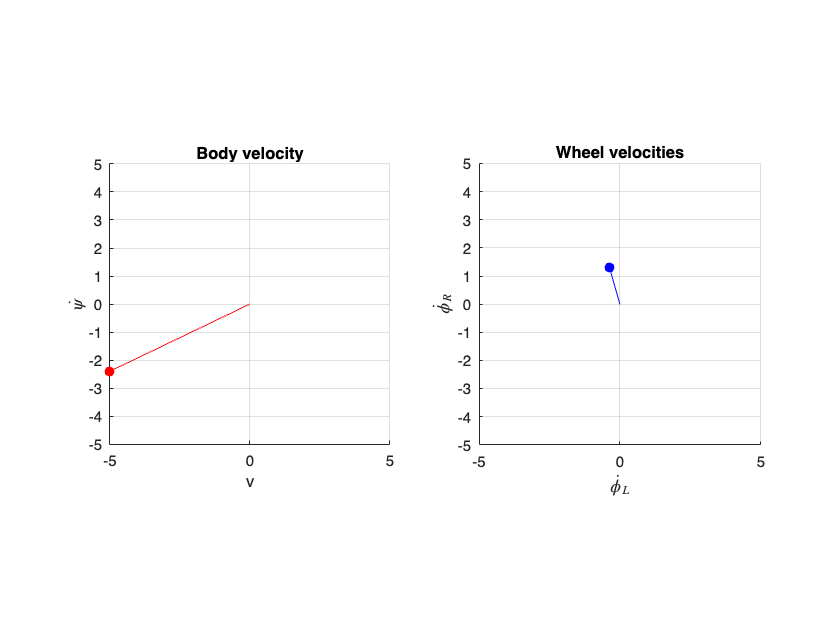

v =-5;
psi_dot =-2.4;

r_W = 0.1;
d = 0.2;

A = 1/r_W*[1 -d/2; 1 d/2];

phi_dot_LR = A\[v psi_dot]';

figure(1),clf
subplot(1,2,1),hold on,grid on,axis equal
plot(v,psi_dot,'ro',MarkerFaceColor='r')
line([0 v],[0 psi_dot],"color",'r')
xlabel('v'),ylabel('$\dot\psi$',Interpreter='latex')
xlim([-5,5]),ylim([-5,5]),title('Body velocity')

subplot(1,2,2),hold on,grid on,axis equal
plot(phi_dot_LR(1),phi_dot_LR(2),'bo',MarkerFaceColor='b')
line([0 phi_dot_LR(1)],[0 phi_dot_LR(2)],"color",'b')
xlabel('$\dot\phi_L$',Interpreter='latex'),ylabel('$\dot\phi_R$',Interpreter='latex')
xlim([-5,5]),ylim([-5,5]),title('Wheel velocities')

### 6.3.4 Determining pose using odometry 

The equation above only gives us a means of finding the robot *velocity* in the world frame. The procedure of calculating the actual pose from velocity information is known as *odometry*. 

#### **Definition:** Odometry

**Odometry** is the use of data from motion sensors to estimate change in position over time. 

Conceptually, the process is quite simple; we have a description of velocity information in $\{W\}$, and if we integrate from  $t=0$ to the current time, we should be able to obtain the corresponding pose information (assuming the integration is exact), namely


$${^W{\mathbf \xi}_B}=\int_{0}^{t} {^W\dot{\mathbf \xi}_B} dt.$$


Because we are relying on discrete sensor information we can approximate the robot's pose by summing up speeds over discrete time intervals of $\Delta t$, which yields


$$\begin{array}{ll}
{^W{\mathbf \xi}_B}
&=&\int_{0}^{t} {^W\dot{\mathbf \xi}_B} dt,\\
&\approx & \sum_{k=0}^{n \Delta t}   {\Delta^W{\mathbf \xi}_B}(k),
\end{array}$$


where $\Delta t$ is the sampling time, $n$ is the total number of samples, and $t=n\Delta t$ describes the relationship between the accumulated discrete-time steps and the continuous-time. This can be calculated explicitly using


$$\begin{array}{ll}\left[\begin{array}{cc}    ^W{t_x(k+1)}\\    ^W{t_y(k+1)}\\    \psi(k+1)    \\ \end{array}\right]     
&\approx&      \left[\begin{array}{cc}    ^W{t_x(k)}\\    ^W{t_y(k)}\\    \psi(k)    \\ \end{array}\right]    +    \left[\begin{array}{cc}    ^W\Delta t_x(k)\\    ^W\Delta t_y(k)\\    \Delta \psi(k)    \\ \end{array}\right],\\
&\approx&      \left[\begin{array}{cc}    ^W{t_x(k)}\\    ^W{t_y(k)}\\    \psi(k)    \\ \end{array}\right]    +   \Delta t \left[\begin{array}{cc}    ^W\dot{t}_x(k)\\    ^W\dot{t}_y(k)\\    \Delta \dot{\psi}(k)    \\ \end{array}\right],\\
\end{array}$$


Notably, we are making the assumption that 


$${^W\dot\mathbf\xi}_B(k) =

\left[\begin{array}{cc}    {^W\dot{t}_x(k)} \\ ^W{\dot{ t}_y}(k) \\ ^W\dot\psi(k) \end{array}\right]
$$


remains constant during the sample period $\Delta t$, which in general will not be true — hence the use of the approximation symbol. The hope is that our sample time, $\Delta t$ , is small enough (relative to the time constants associated with our system) such that the approximation is viable (e.g. we cannot expect to use odometry to estimate the position of a high-speed wheeled robot if our sampling time is 1 second!). 

This particular method of calculating the pose is known as *dead reckoning* and is prone to drift over time as a result of the imperfect sensor information and discrete integration. 

#### **Definition:** Dead reckoning

In navigation, **dead reckoning** is the process of calculating the current position of some moving object by using a previously determined position, or fix, and then incorporating estimations of speed, heading direction, and course over elapsed time. 

This can be particularly problematic if accurate pose information is required to fulfill a given task over a long period of time. A solution to this problem is to incorporate this information in a pose estimator that can correct drift effects. We have already seen examples of this in **Chapter 4**, where an explicit complementary filter was able to account drift resulting from imperfect gyroscope integration. Similar solutions are appropriate for wheeled robots, such as computer vision, but this will not be explored in this course.

In the case of the wheeled robot, the wheel speeds are only measurement available, and this information is passed through the forward kinematics and integrated. A number of factors can result in drift of the robot pose, such as:

- imperfect wheel speed measurements,

- wheel speed sensor noise and resolution issues,

- wheel slip/skid,

- wheel speed not being constant during the sampling instance.

#### Example: Using dead reckoning to determine the pose of the robot

The example below estimates and visualises the robot pose over time given knowledge of the wheel speeds at every sampling instance. You should notice that

- when $\dot\phi_L>\dot\phi_R$ the robot turns right,

- when $\dot\phi_R>\dot\phi_L$ the robot turns left,

- when $\dot\phi_R=\dot\phi_L$ the robot drives straight,

- when $\dot\phi_R=-\dot\phi_L$ the robot turns on the spot.

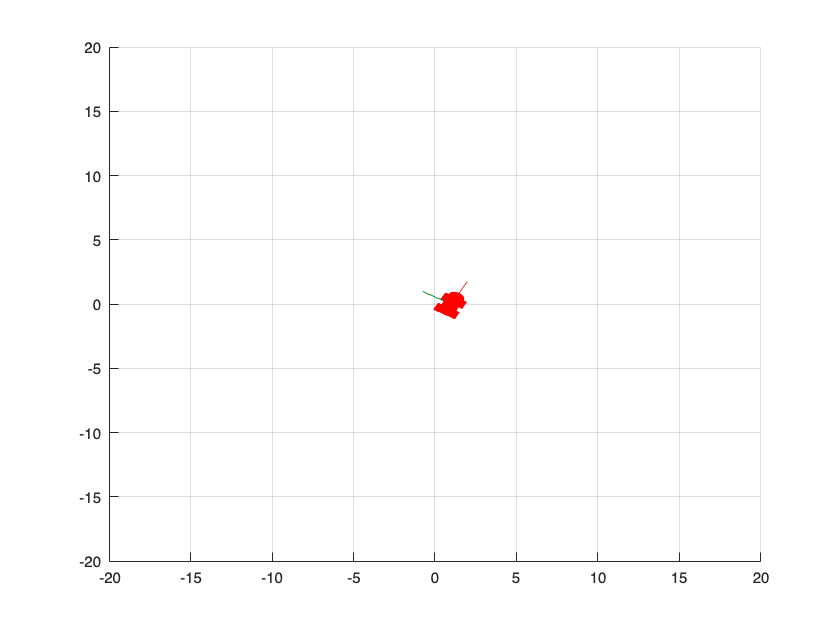

clear
kinematicModel = differentialDriveKinematics(WheelRadius=0.5,TrackWidth=0.2,VehicleInputs="WheelSpeeds");
dT = 0.1;

timer = rateControl(1/dT);  %set up a timer with a duration of dT seconds.

phiL = 8; %rad/s
phiR = -8; %rad/s

robotPose = [1 0 0]';
for i=1:(5/dT)  %run the simulation for a time equivalent to 5 seconds
    figure(1),clf

    robotVelocity = derivative( kinematicModel,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation
    
    axis([-20 20 -20 20])   %sets x- and y-axis limits.
    grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", 10*kinematicModel.TrackWidth);
    drawnow

    waitfor(timer);
end

## 6.4 Inverse kinematics of wheeled robots

Because of the non-holonomic nature of our wheeled robot, we cannot find an algebraic relationship between our robot wheel angles or velocities and its position in space. For this reason, we will only consider the objective of generating the correct wheel speeds given *desired velocities* in the world frame. 

### 6.4.1 The non-holonomic kinematic constraint

The high-level relationship between the velocities in $\{B\}$ and $\{W\}$ has already shown to be


$$\left[\begin{array}{cc}    {\dot{t}_x} \\ {\dot{ t}_y}  \\ \dot\psi \end{array}\right]=\left[\begin{array}{cc}    v\cos\psi \\ v\sin\psi\\ \dot\psi  \end{array}\right]=\left[\begin{array}{cc}    \cos\psi & 0\\ \sin\psi & 0\\ 0 & 1  \end{array}\right]
\left[\begin{array}{cc}    v \\ \dot\psi  \end{array}\right].$$


Notably, our actuation space, spanned by $\{v,\dot\psi\}$, is two-dimensional. As such, we cannot obtain an arbitrary pose rate. Analogous to the 2R robot arm, we must relinquish control over choosing the angular velocity. The truncated relationship, considering only desired position, follows as


$$\left[\begin{array}{cc}    {\dot{t}_x^*} \\ {\dot{ t}^*_y}   \end{array}\right]=\left[\begin{array}{cc}    v\cos\psi \\ v\sin\psi \end{array}\right],$$


where the asterisk $*$ indicates a desired quantity. Note that $\dot\psi$ does not affect the position of the robot with the current choice of reference frame location. The required velocity in the frame $\{B\}$ $x$-axis is then given by

$v=\frac{{\dot{ t}^*_x}}{\cos\psi}=\frac{{\dot{ t}^*_y}}{\sin\psi}$.

The equation above can be expressed as


$${{\dot{ t}^*_x}}{\sin\psi}={{\dot{ t}^*_y}}{\cos\psi},$$


which implies that


$${{\dot{ t}^*_x}}{\sin\psi}-{{\dot{ t}^*_y}}{\cos\psi}=0.$$


The equation above describes the non-holonomic kinematic constraint directly, which must be adhered to for any conventionally-wheeled robot. For example, when $\psi=0$ (implying that $\{B\}$ and $\{W\}$ have the same orientation, the equation above implies that ${{\dot{ t}^*_y}}=0$. In other words, velocity cannot instantaneously be achieve in the direction of $\hat{\bf y}_W$.

### 6.4.2 Inverse kinematic solution with adjusted body-frame location

The problem with the formulation in the previous section is that angular velocity term $\dot\psi$ does not contribute to the position of the robot in $\{W\}$ based on the choice of placing the origin of $\{B\}$ to be coincident with the wheel-to-wheel centre. As a result, one has no control over adjusting the orientation of the vehicle — all we could do is increase/decrease $v$. To circumvent this issue, we can redefine our chosen location of the body-frame origin. 

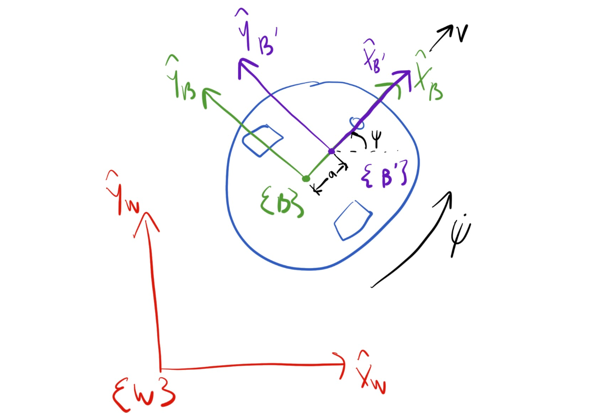

**Figure 6.6:** Differentially-steered robot with two frames attached to robot body. Frame $\{B'\}$ is displaced from frame $\{B\}$ to avoid matrix inversion issues.

With reference to Figure 6.6, if we use frame $\{B'\}$ as our new body-frame description, then our linear velocity in $\{B'\}$ is given (with some abuse of notation) by


$${^{B'}{\bf v}}=[v~~a\dot\psi]^T.$$
 

The corresponding velocity in$\{W\}$ is determined using


$$\begin{array}{cc}\left[\begin{array}{cc}    {^W\dot{t}_x^*} \\    ^W\dot{t}_y^*     \\ \end{array}\right] =     {^W{\bf R}_{B'}} {^{B'}{\bf v}, \end{array}$$


where ${^W{\bf R}_{B'}}={^W{\bf R}_{B}}$. The relationship above can be expressed as


$$\begin{array}{cc}\left[\begin{array}{cc}    {^W\dot{t}_x^*} \\    ^W\dot{t}_y^*     \\ \end{array}\right] =     \left[\begin{array}{cccc}    \cos{\psi} & -a \sin{\psi}\\    \sin{\psi} & a \cos{\psi}\\    \\ \end{array}\right]    \left[\begin{array}{cc}    v\\    \dot{\psi}    \\ \end{array}\right], \end{array}$$


which exposes the mapping from body velocities to the world-frame translational velocity. 

Our matrix mapping will now have a nonzero determinant (if $a\neq 0$ ), and we can solve for our body-frame velocities using 


$$\begin{array}{cc}\left[\begin{array}{cc}    v\\    \dot{\psi}    \\ \end{array}\right]=    \left[\begin{array}{cccc}    \cos{\psi} & \sin{\psi}\\    -\frac{1}{a}\sin{\psi} & \frac{1}{a} \cos{\psi}\\    \\ \end{array}\right]\left[\begin{array}{cc}    {^W\dot{t}_x^*} \\    ^W\dot{t}_y^*     \\ \end{array}\right] .\end{array}$$


syms tx_dot ty_dot psi a real

A = [cos(psi) -a*sin(psi);
     sin(psi)  a*cos(psi)];
t = [tx_dot ty_dot]';
u = A\t;
u = simplify(expand(u))

$$u = \left(\begin{array}{c} \dot{\mathrm{tx}}\,\cos\left(\psi \right)+\dot{\mathrm{ty}}\,\sin\left(\psi \right)\\ \frac{\dot{\mathrm{ty}}\,\cos\left(\psi \right)-\dot{\mathrm{tx}}\,\sin\left(\psi \right)}{a} \end{array}\right)$$

The equation above describes the required linear and angular velocities of the robot to achieve arbitrarily defined velocities $({^W\dot{t}_x^*},{^W\dot{t}_y^*})$, which correspond to the velocity of the frame $\{ B'\}$ origin (no longer $\{B\}$). This configuration is appealing when addressing the trajectory tracking problem, which will be detailed in **Chapter 8**. 

While the robot is now able to instantaneously move in any direction on the $\hat{\bf x}_W$-$\hat{\bf y}_W$ plane, it is still a non-holonomic system. This is because the configuration space is made up $\{t_x,t_y,\psi\}$, and the newly coupled nature between translational and angular velocity (from using $\{B'\}$) means that the robot cannot simultaneously perform an arbitrary rotational *and *translational velocity. 

The mapping above requires knowledge of the orientation $\psi$ at all times. Otherwise it would not be possible to map between frames. Assuming the orientation is sufficiently well known, the desired velocities in $\{B\}$ can be obtained using the equation above, given a desired velocity vector in $\{W\}$. 

With reference to Section 6.3.3, the wheel speeds can be determined using


$$\begin{array}{ll}\left[\begin{array}{cc}    \dot\phi_L \\   \dot\phi_R \end{array}\right] 
&=&     \frac{1}{r_W}\left[\begin{array}{cccccccc}    1 & -\frac{d}{2}\\    1 & \frac{d}{2} \end{array}\right]    \left[\begin{array}{cc}    v \\ \dot\psi    \end{array}\right],\\
&=&   \frac{1}{r_W}\left[\begin{array}{cccccccc}    1 & -\frac{d}{2}\\    1 & \frac{d}{2} \end{array}\right] \left[\begin{array}{cccc}    \cos{\psi} & \sin{\psi}\\    -\frac{1}{a}\sin{\psi} & \frac{1}{a} \cos{\psi}\\    \\ \end{array}\right]\left[\begin{array}{cc}    {^W\dot{t}_x^*} \\    ^W\dot{t}_y^*     \\ \end{array}\right].

\end{array}$$


#### Example: Following a trajectory using inverse kinematics

The example below shows how a position trajectory can be followed if the time derivative is known. Using $\{B'\}$ with $a>0$, the robot can follow the trajectory. You should notice that

- the frame $\{B\}$ origin does not follow the trajectory. Instead, the $\{B'\}$ axis moves along the trajectory,

- choosing too small an $a$ value makes the matrix above approach a singularity, which leads to erroneous behaviour

- choosing too large an $a$ value makes the trajectory tracking nonsensical, as the point following the path is far removed from the robot body.

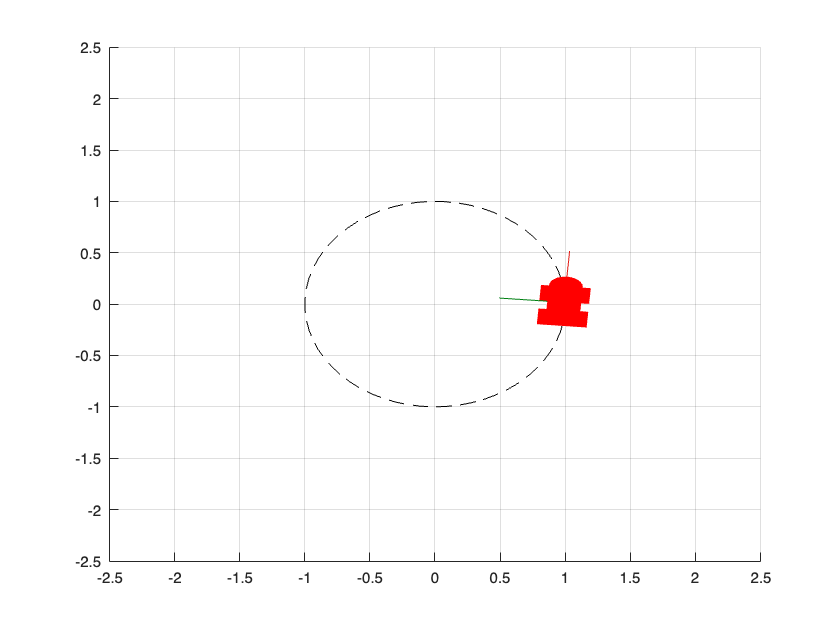

clear

kinematicModel = differentialDriveKinematics(WheelRadius=1,TrackWidth=0.5,VehicleInputs="WheelSpeeds");
dT = 0.1;
timer = rateControl(1/dT);

a =0.1;
d = kinematicModel.TrackWidth;
r_w = kinematicModel.WheelRadius;

time = 0:dT:2*pi;
t_des = [cos(time)' sin(time)'];
t_dot_des = [-sin(time)' cos(time)'];

robotPose = [1 0 pi/2]';
for i=1:length(time)  %run the simulation for a time equivalent to 5 seconds

    psi = robotPose(3);
    A1 = [1 -d/2;
          1  d/2];
    A2 = [     cos(psi)     sin(psi);
          -1/a*sin(psi) 1/a*cos(psi)];
    wheelSpeeds = 1/r_w*A1*A2*t_dot_des(i,:)';

    robotVelocity = derivative( kinematicModel,robotPose, wheelSpeeds );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    figure(1),clf,hold on
    axis(2.5*[-1 1 -1 1]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", kinematicModel.TrackWidth);
    plot(t_des(:,1),t_des(:,2),'--k')
    title([])

    drawnow
    waitfor(timer);
end